# Lab 3

## Kurt Delegard

## PHYS 434 AB

### Problem 1.

*In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.*

Assuming the temperature fluctuations form a Gaussian distribution, we can model the temperature data as a Gaussian distribution with a mean of 12 K and a standard deviation of 0.4:

clear;
clc;
clf;

mu = 12;
sig = 0.4;

xs = linspace(0, 24, 1000);
temp = makedist("Normal", "mu", mu, "sigma", sig);

To make this scenario more realistic, we will add in "bad" data - intentional outliers that are far away from the mean of the temperature distribution.

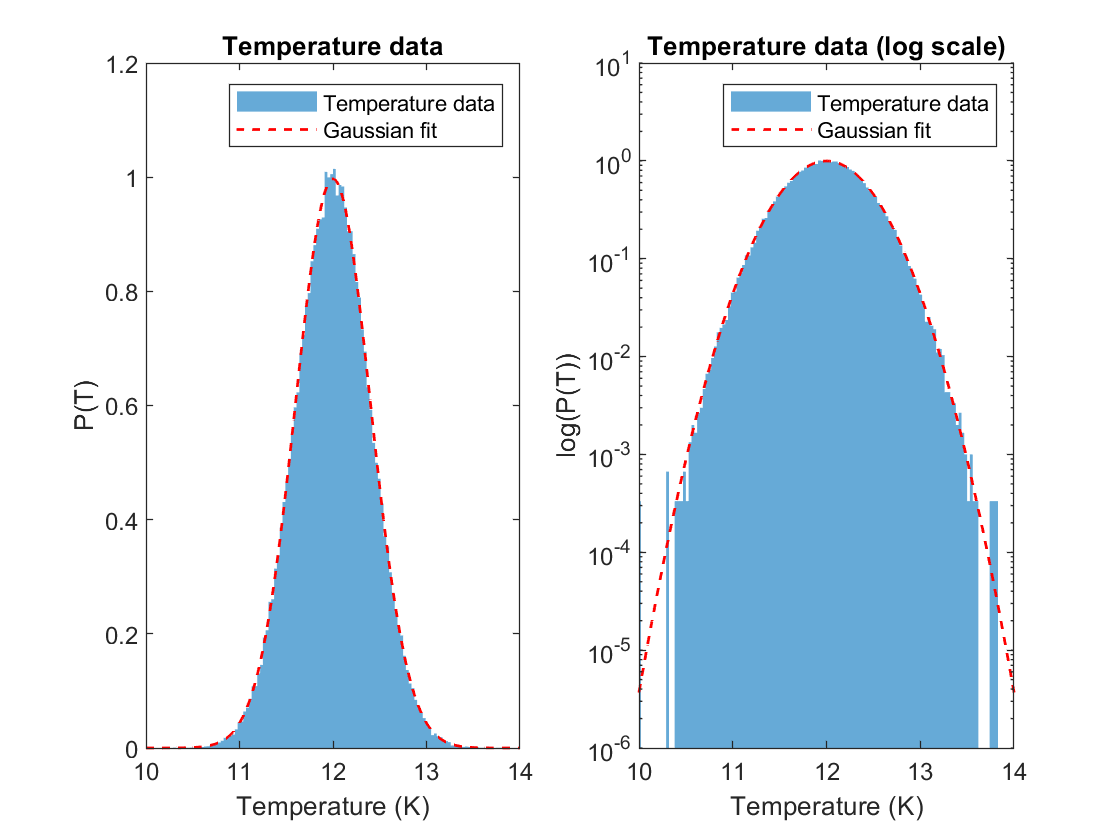

bad_data = [10. 10.3 2.1 0. 0. 15.6 22.3 12.7];
good_data = random(temp, [1, 100000]);

%Total temperature data = good data + bad data
meta_data = [good_data, bad_data];

%Gaussian distribution fit
normys = normpdf(xs, mu, sig);

subplot(1, 2, 1);
histogram(meta_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor', 'none'), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);

xlim([10, 14])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('P(T)')
title('Temperature data');
subplot(1, 2, 2);
histogram(meta_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor',"none"), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);
set(gca,'YScale','log')

xlim([10, 14])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('log(P(T))')
title('Temperature data (log scale)')

This data seems to pretty accurately follow a Gaussian trend. However, zooming out to see the full range of data:

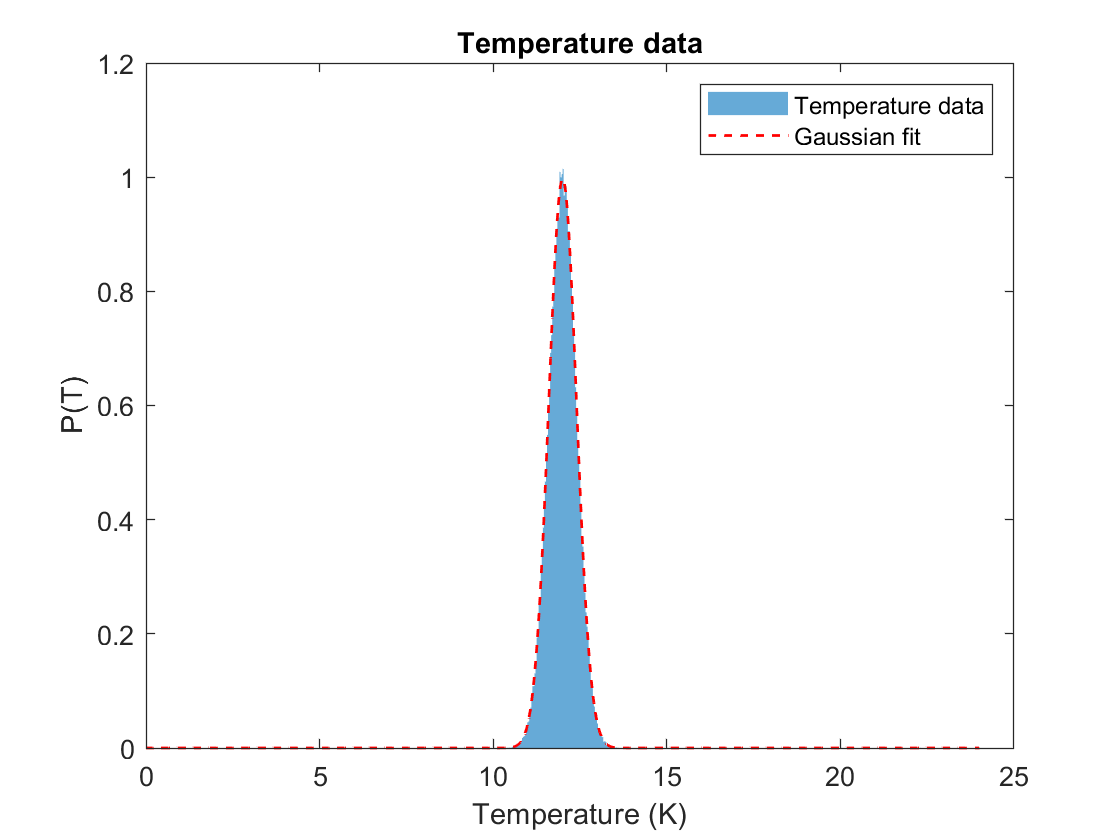

clf;

histogram(meta_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor', 'none'), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);

xlim([0, 25])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('P(T)')
title('Temperature data');

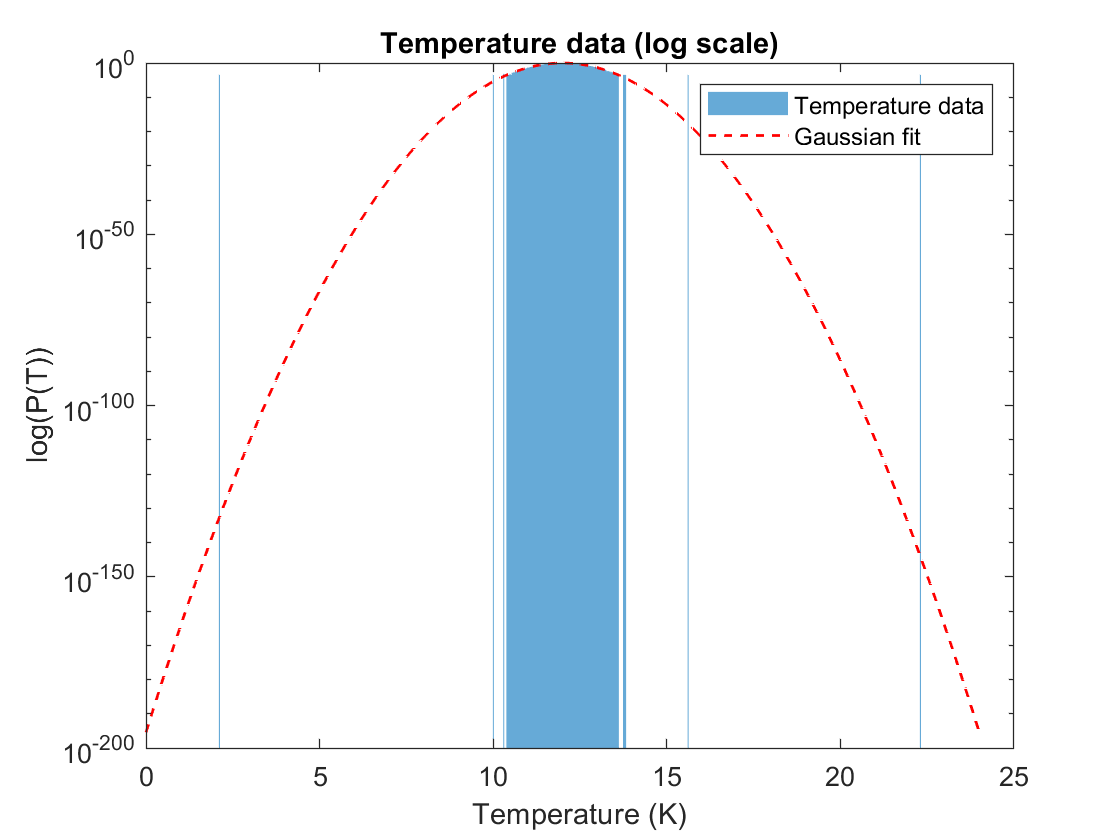


clf;
histogram(meta_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor',"none"), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);
set(gca,'YScale','log')

xlim([0, 25])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('log(P(T))')
title('Temperature data (log scale)')

There are several outliers (which we added in) that could cause problems in our analysis.

We want to identity the bad data and exclude it from our results.

Steps:

- Identify/define outliers

- Remove the outliers

- Compare the new data set with the original data set; determine how much good data and how much bad data was expunged

- Solve optimization problem to find the best criteria for outliers based on results from 3.

First, let's define the outliers in this data. Say, to begin with, we want to only keep the data within $\pm 5\sigma$ of the mean. Can we find the outliers that exceed this range of values?

threshold = 5 * sig;
outliers = meta_data(meta_data < (mu - threshold) | meta_data > (mu + threshold))

outliers =     2.1000         0         0   15.6000   22.3000


While this correctly determines some of the outliers that we added, it did not pick out all of them. We need to find an optimal value of $X*\sigma$ that removes all our bad data and keeps all our good data.

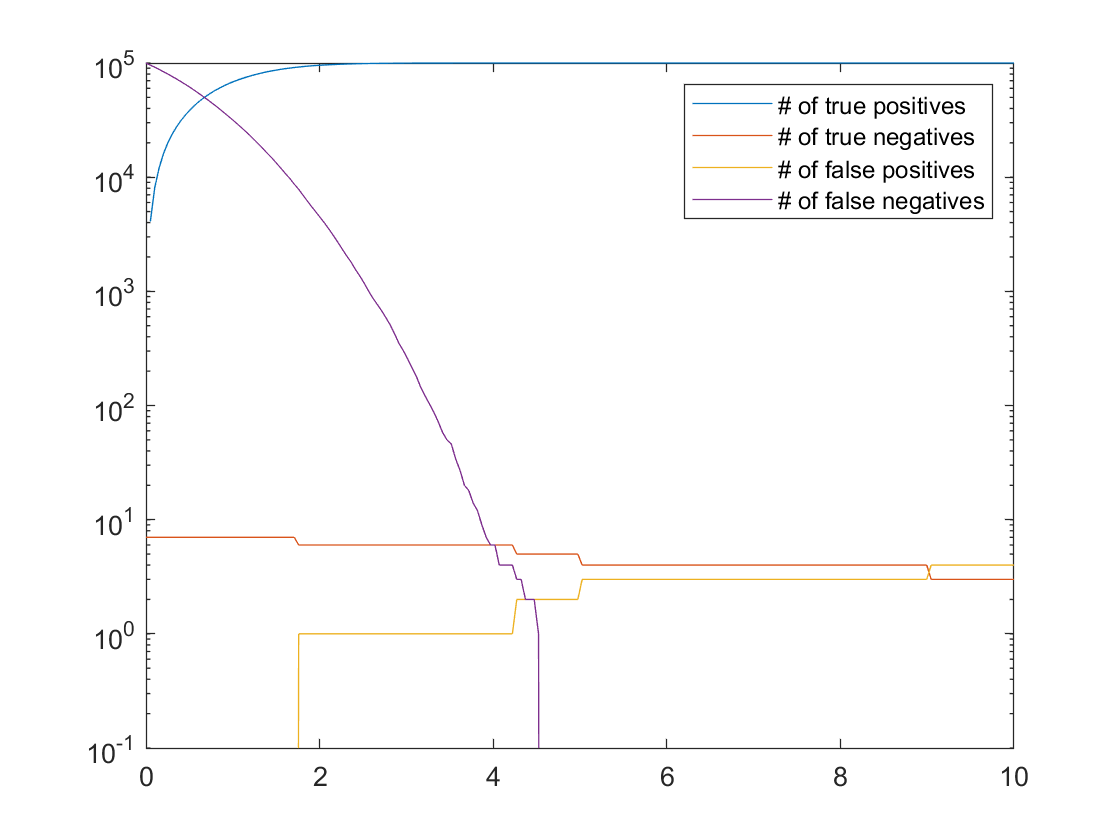

true_pos = [];
true_neg = [];
false_pos = [];
false_neg = [];

sigmas = linspace(0, 10, 200);
for ii = sigmas
    
    outliers = meta_data(meta_data < (mu - ii * sig) | meta_data > (mu + ii * sig));
    
    clean_data = meta_data(~ismember(meta_data, outliers));
    
    true_pos = [true_pos, length(intersect(good_data, clean_data))];
    true_neg = [true_neg, length(intersect(bad_data, outliers))];
    false_pos = [false_pos, length(intersect(bad_data, clean_data))];
    false_neg = [false_neg, length(intersect(good_data, outliers))];
    
end

clf;

plot(sigmas, true_pos), hold on;
plot(sigmas, true_neg);

%MATLAB has trouble plotting 0 on a log plot
plot(sigmas, false_pos + 1e-23);
plot(sigmas, false_neg + 1e-23);
set(gca, 'YScale', 'log');
legend('# of true positives', '# of true negatives', '# of false positives', '# of false negatives');
ylim([1e-1 1e5]);

[~, index] = min(false_neg+false_pos)

index = 92

optimal_sigma = sigmas(index)

optimal_sigma = 4.5729

[~, index] = max(true_neg + true_pos)

index = 92

optimal_sigma = sigmas(index)

optimal_sigma = 4.5729

Mistakes of omission = false negatives

Mistakes of commission = false positives; avoidable if you pick a very low sigma, but you throw out much more good data (false negatives goes way up)

Relation between curves: By increasing your range, a bad data point becomes a good data point

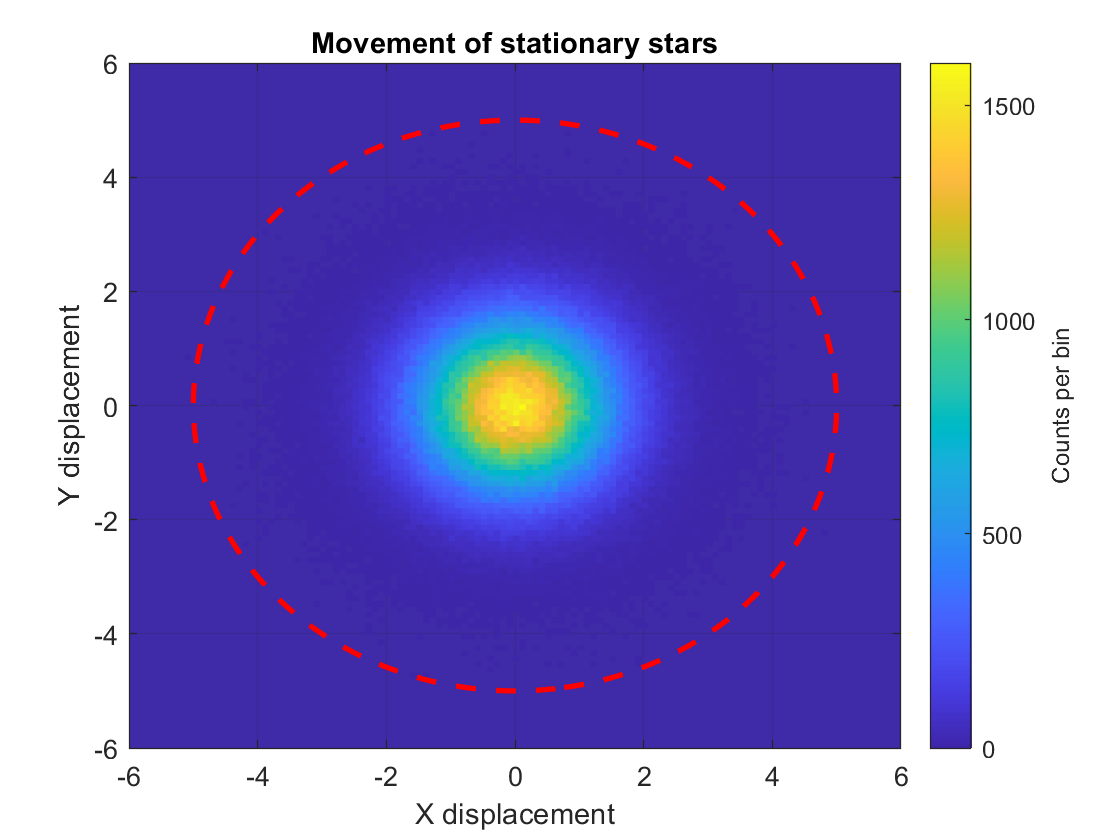

clc;
clear;
clf;

a = random('Normal', 0, 1, [2, 1e6]);
xs = a(1, :);
ys = a(2, :);
histogram2(xs, ys, 100, 'DisplayStyle', 'tile'), hold on;
c = colorbar;
set(gca,'Color','#3F2AA7');
xlim([-6 6])
ylim([-6 6])

r=5;
fimplicit(@(x, y) x.^2 + y.^2 - r .^ 2, 'r--', 'linewidth', 2)
title('Movement of stationary stars')
xlabel('X displacement');
ylabel ('Y displacement');
c.Label.String = "Counts per bin";

What is the distance away from the origin at which the 2-dimensional Gaussian distribution has a significance of 5 sigma or more?

Numerically: Integrate from 0 to 5 sigma (5 * 1) and subtract from 2 pi

% twodgauss = @(r) (2*pi) * (r .* exp((-(r .^ 2)) ./ 2));
% twodgauss(5)
% area_inside = integral(twodgauss, 0, 5) ./ (2*pi)
% area_outside = 1-area_inside
% sigma = norminv(area_outside)

Noticing that the radial pdf takes the form of a Rayleigh distribution helps us greatly in calculating the probability of a 5 sigma event. 

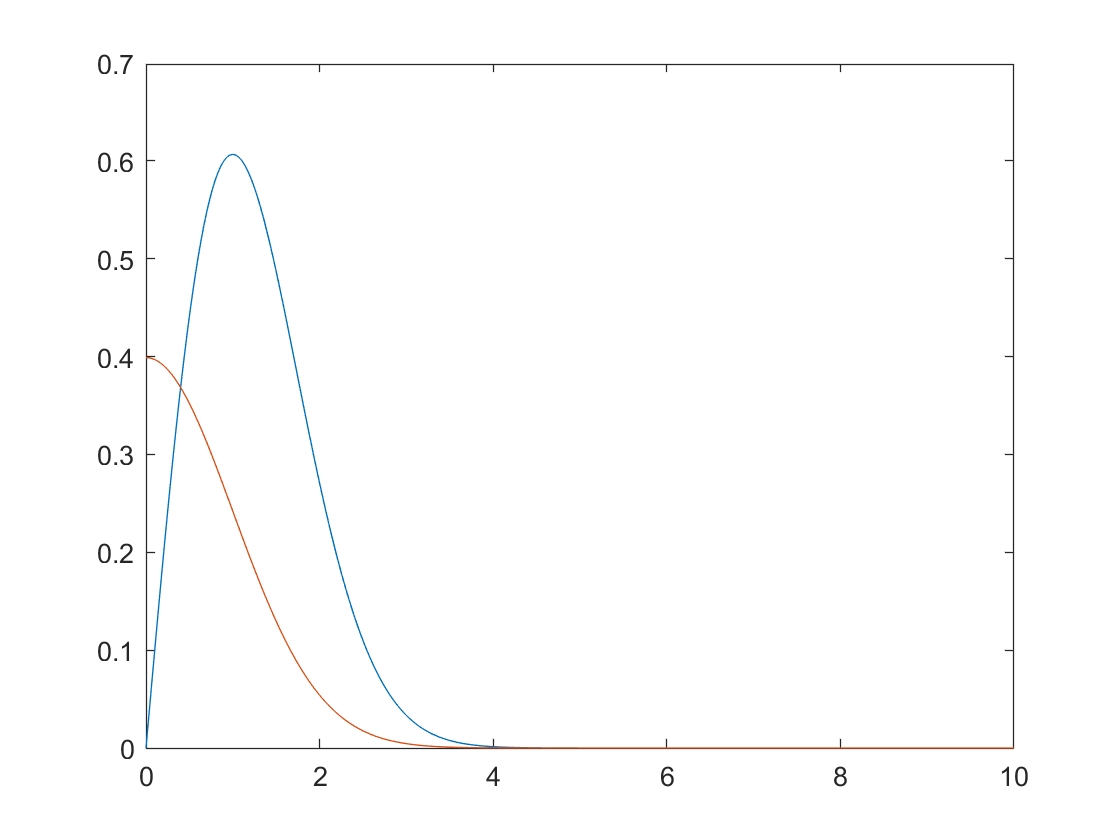

pdfxs = linspace(0, 10, 1000);
pdfys_rayl = raylpdf(pdfxs, 1);
pdfys_gauss = normpdf(pdfxs, 0, 1);

clf;
plot(pdfxs, pdfys_rayl), hold on;
plot(pdfxs, pdfys_gauss);

prob_gaussian = 1-normcdf(5, 0, 1)

prob_gaussian = 2.8665e-07

distance = icdf('Rayleigh', 1-prob_gaussian, 1)

distance = 5.4891

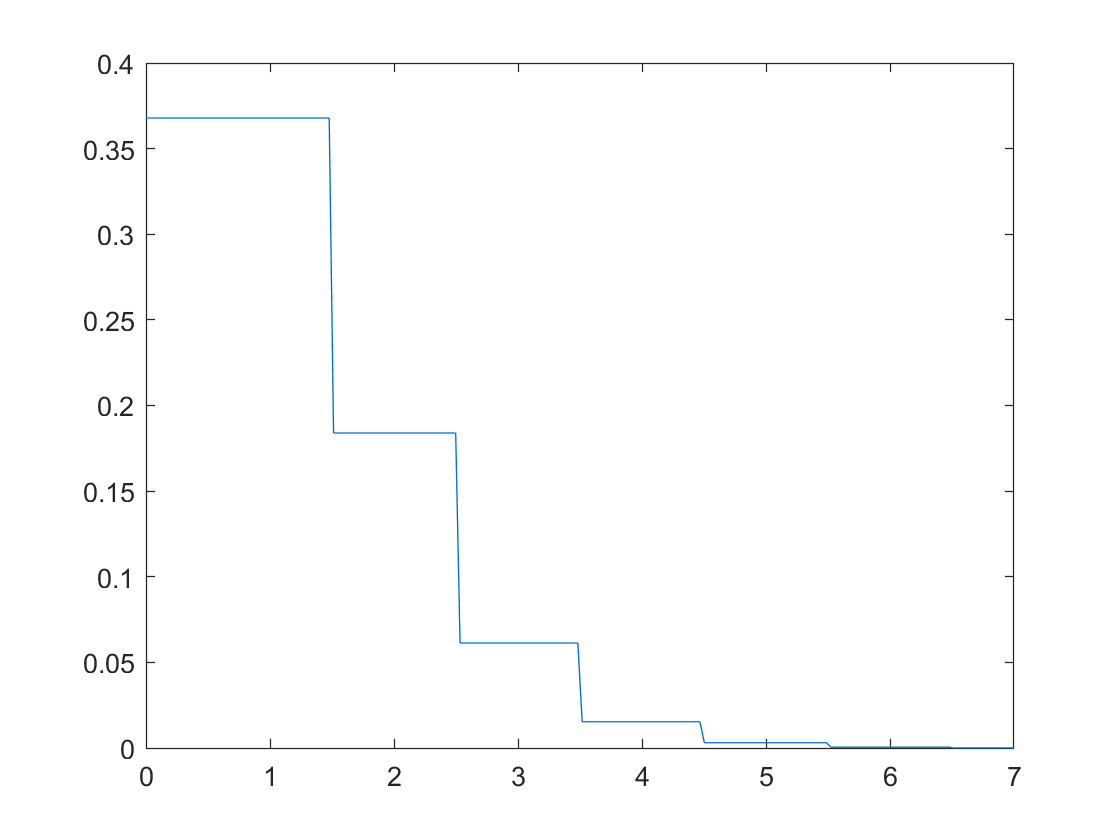

clear;
clc;
clf;

xs = 0:7;
pdf_1min = poisspdf(xs, 1);
xq = linspace(0, 7, 200);
yq = interp1(xs, pdf_1min, xq, 'nearest');

plot(xq, yq);

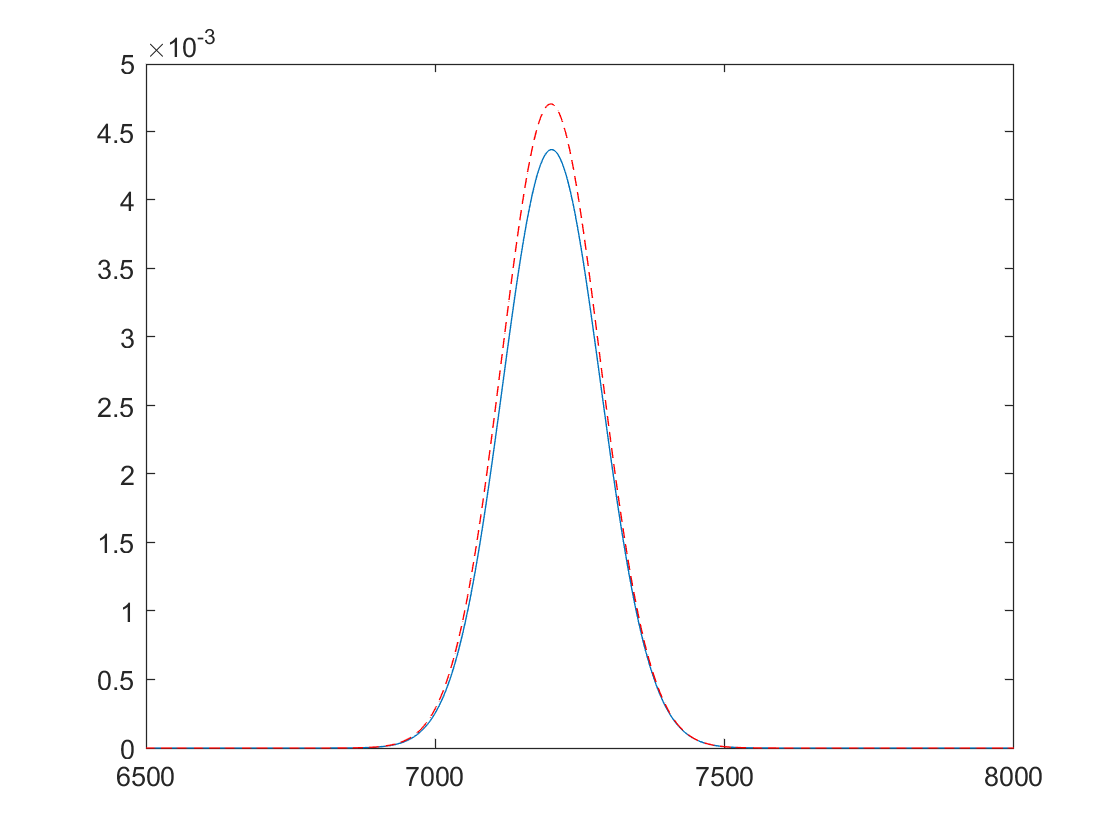


clf;

pdf_15days = pdf_1min;
%not a trials factor, the mean changes

for ii = 1:7200
    pdf_15days = conv(pdf_15days, pdf_1min);
end
plot(1:length(pdf_15days), pdf_15days), hold on;

xs2 = 6500:8000;
plot(xs2, poisspdf(xs2, 7200), 'r--')
xlim([6500 8000])